# **Ch6 Color image processing**

## **RGB color space**

rgbcube(1,1,1)

未定义函数或变量 'rgbcube'。


im_input = im2double(imread('.\Pics\Ch06\Chalk.jpg'));
figure,imshow(im_input),title('原图');

im_input_r = im_input(:,:,1);
im_input_g = im_input(:,:,2);
im_input_b = im_input(:,:,3);
figure, imshow(im_input_r,[]), title('R通道图');
figure, imshow(im_input_g,[]), title('G通道图');
figure, imshow(im_input_b,[]), title('B通道图');

im_input_r1 = 1-im_input_r;
im_input_g1 = 1-im_input_g;
im_input_b1 = 1-im_input_b;

im_output = cat(3,im_input_r1,im_input_g1,im_input_b1);

figure, imshow([im_input im_output]), title('彩色原图和反色结果图');

## **CMYK color space**

im_input = im2double(imread('.\Pics\Ch06\photo.jpg'));
im_output = imcomplement(im_input);
figure,imshow([im_input im_output]),title('原图');



## **HSI color space**

im_input = im2double(imread('.\Pics\Ch06\scene.png'));

im_hsi = rgb2hsi(im_input);
im_hsi_h = im_hsi(:,:,1);
im_hsi_s = im_hsi(:,:,2);
im_hsi_i = im_hsi(:,:,3);

figure,imshow(im_input),title('原图');
figure,colormap('hsv'),imshow(im_hsi_h),title('H分量：色调'); % 加上颜色
figure,imshow(im_hsi_s),title('S分量：饱和度');
figure,imshow(im_hsi_i),title('I分量：强度');

## **HSI color space 2**

im_input = im2double(imread('.\Pics\Ch06\color_bars.tif')); 
im_hsi = rgb2hsv(im_input);
im_hsi_h = im_hsi(:,:,1);
im_hsi_s = im_hsi(:,:,2);
im_hsi_i = im_hsi(:,:,3);

figure,imshow(im_input),title('原图');
figure,imshow(im_hsi_h),title('H分量：色调'); % 加上颜色
figure,imshow(im_hsi_s),title('S分量：饱和度');
figure,imshow(im_hsi_i),title('I分量：强度');

## Pseudocolor Processing : Intensity Slicing 1

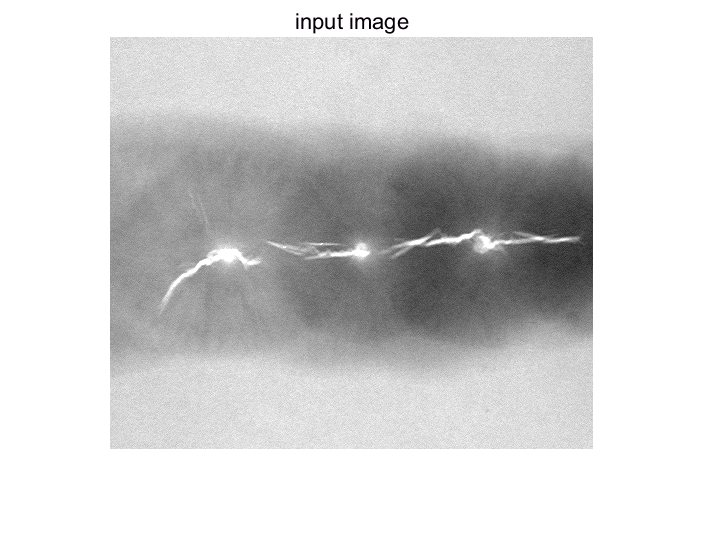

im_input = im2double(imread('.\Pics\Ch06\weld.tif'));
figure, imshow(im_input),title('input image');

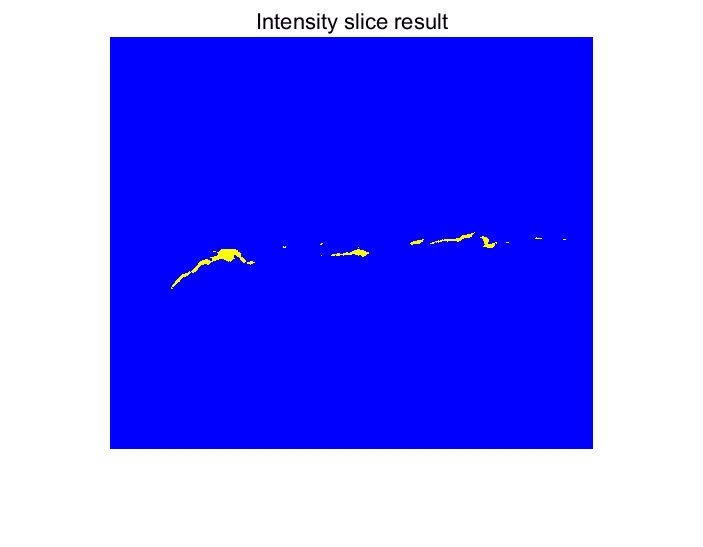

[im_h,im_w] = size(im_input);

im_bw = im2bw(im_input,254/255);

im_output = cat(3,im_bw,im_bw,1-im_bw);

figure;imshow(im_output),title('Intensity slice result');

## Pseudocolor Processing : Intensity Slicing 2

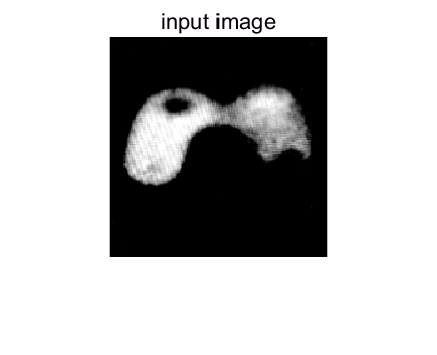

im_input = im2double(imread('.\Pics\Ch06\picker_phantom.tif'));
im_input = imadjust(im_input);
figure, imshow(im_input),title('input image');

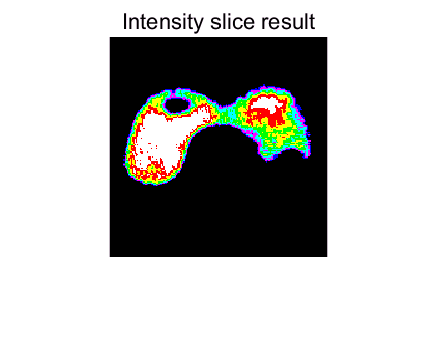

[im_h,im_w] = size(im_input);

im_output = grayslice(im_input,8);
%colormap
mymap = [0,0,0;0,0,1;1,0,1;0,1,1;0,1,0;1,1,0;1,0,0;1,1,1];
figure;imshow(im_output,mymap),title('Intensity slice result');

## Pseudocolor Processing : Intensity Slicing 3

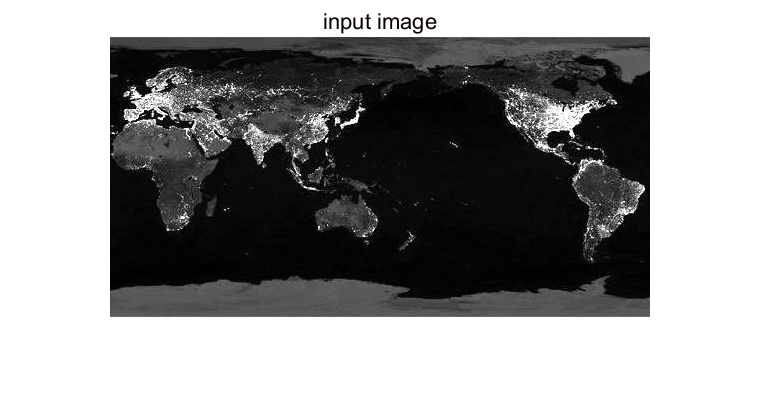

im_input = rgb2gray(imread('.\Pics\Ch06\world_light.jpg'));
im_input = imadjust(im_input);
figure, imshow(im_input),title('input image');

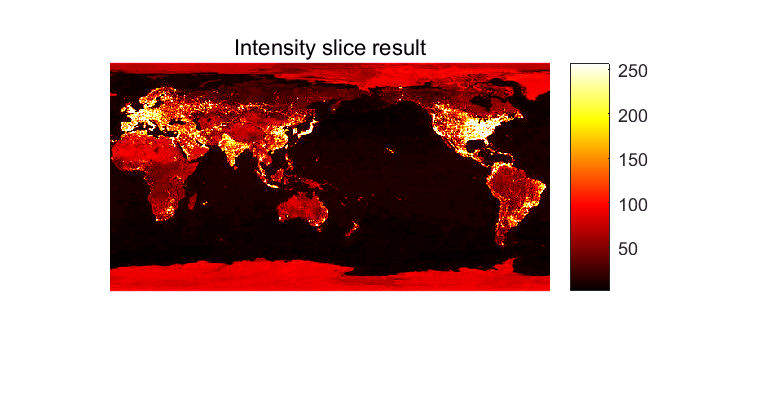

[im_h,im_w] = size(im_input);

im_output = grayslice(im_input,256);% colormap
figure;imshow(im_output,jet(256)),title('Intensity slice result');
colorbar

## Pseudocolor Processing : Gray-level to Color Transformation

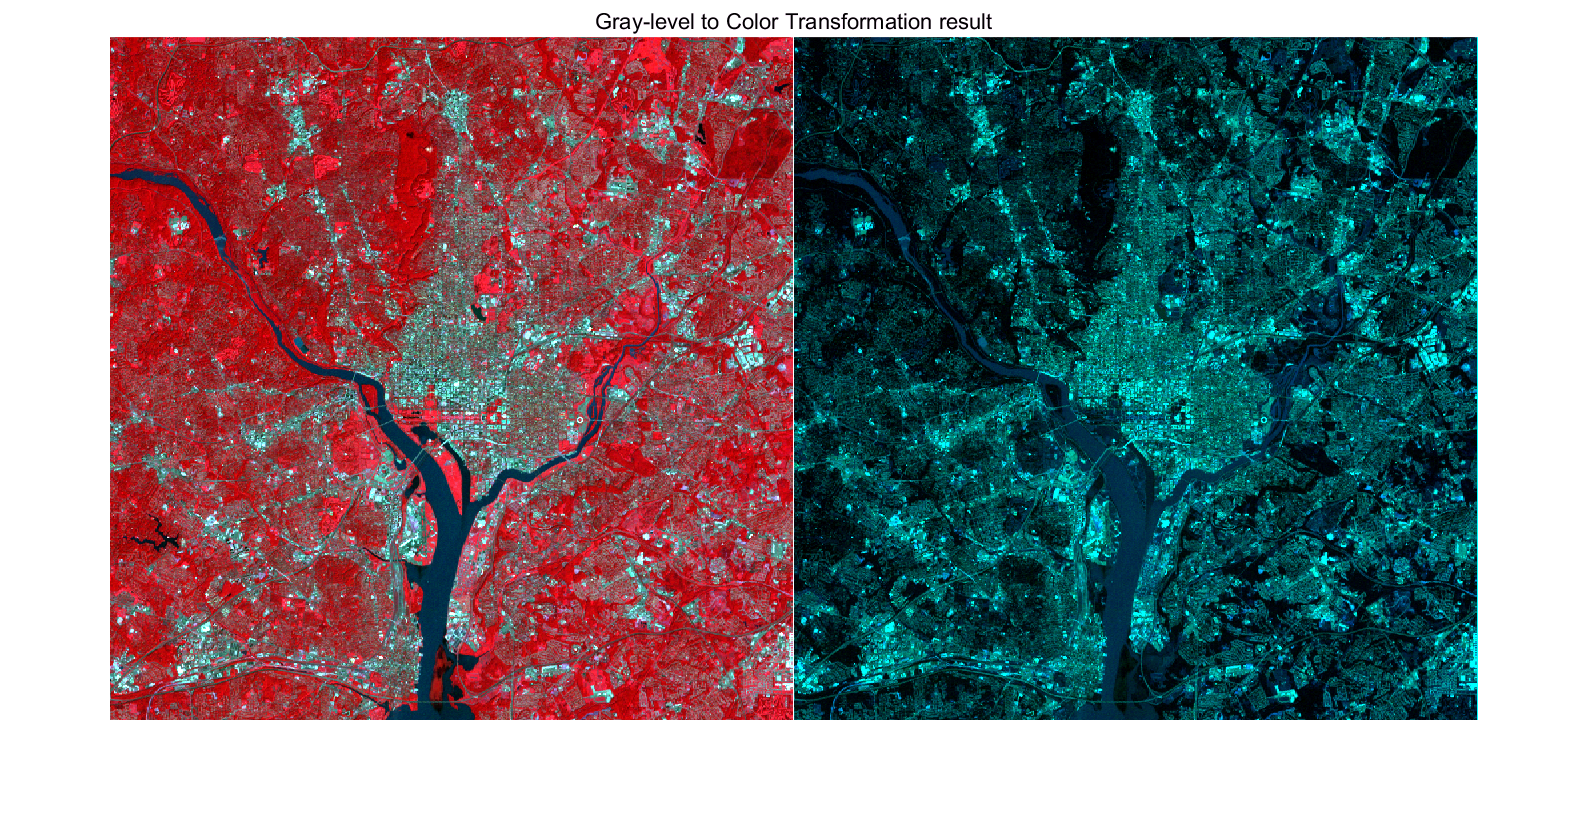

im_input1 = imread('.\Pics\Ch06\WashingtonDC Band_R.tif');
im_input2 = imread('.\Pics\Ch06\WashingtonDC Band_B.tif');
im_input3 = imread('.\Pics\Ch06\WashingtonDC Band_G.tif');
im_input4 = imread('.\Pics\Ch06\WashingtonDC Band4.tif');

im_color1 = cat(3,im_input1,im_input2,im_input3);
im_color2 = cat(3,im_input4,im_input2,im_input3);
im_color3 = cat(3,1-imadjust(im_input4),imadjust(im_input2),imadjust(im_input3));
figure;imshow([im_color2 im_color3]),title('Gray-level to Color Transformation result');